# Speed RAM

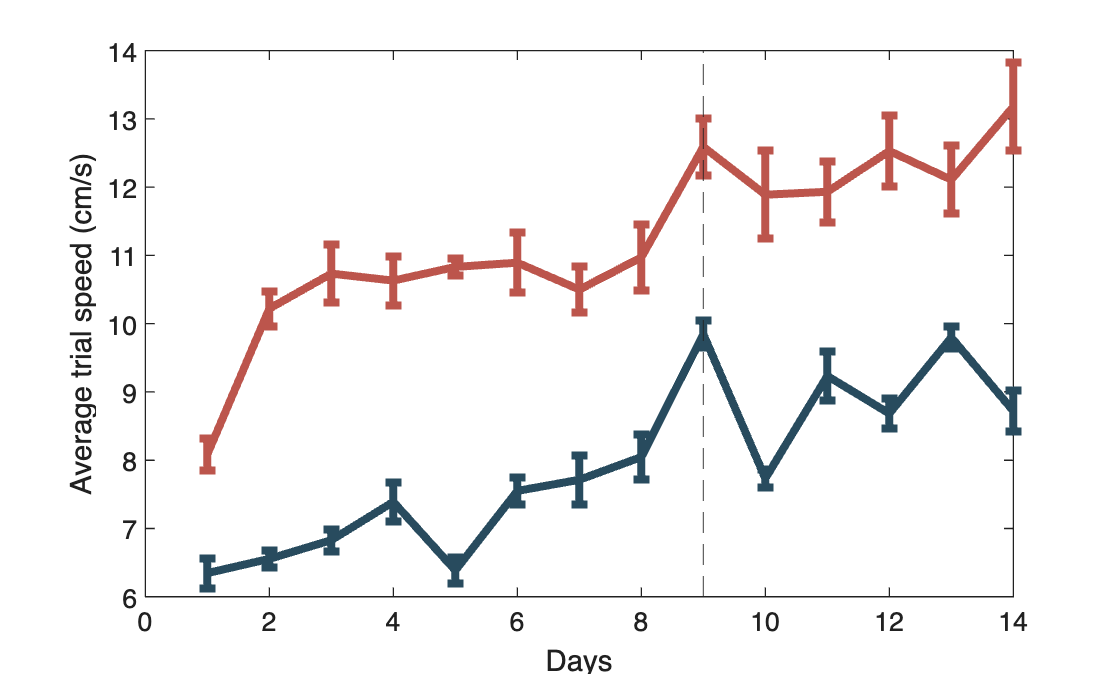

clear; close all; clc;

load(fullfile(get_behavior_root(),"SpeedRAM.mat"));
load(fullfile(get_behavior_root(),"RAMdata.mat"));

% Meta data
animals = length(Data.animal);
arms = 8;
trial = length(Data.animal(3).trial); % habituation + 8 days phase 1 + 6 days phase 2
experiment = trial - 5;
phase1_idx = 1:64;
phase2_idx = 65:112;
days = [1:8; 9:16; 17:24; 25:32; 33:40; 41:48; 49:56; 57:64; 65:72; 73:80; 81:88; 89:96; 97:104; 105:112];

incorrect = [1,2,5,6,8];
correct = [3,4,7];
positive = [6,8,9,10]; % 11 check injection
negative = [2,3,4,5];
start_arm = nan(133,1); %reference
start_arm(1:69) = 2;
start_arm(70:end) = 5;
max_trial_length = max(cellfun(@length,(entry_raw_comp(6:end,:))),[],'all');

%Plot specifications
colors = {'#284B5E','#BC554C'};
noLine = {'none','none'};
linew = {3,3};

% Averages
speed_day = average_matrix(speed_avr(6:end,:),animals,8);
trial_time = average_matrix(trial_length(6:end,:),animals,8);
trial_sum = sum_matrix(trial_length(6:end,:),animals,8);

[speed_genotype,speed_se] = genotype(speed_day,negative,positive);

[trial_genotype,trial_se] = genotype(trial_time,negative,positive);

[trial_accumulated,trial_acc_se] = genotype(trial_sum,negative,positive);


figure
c = plot(speed_genotype,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('Average trial speed (cm/s)');
er = errorbar(speed_genotype,speed_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');

[p,tbl,stats] = anova2(speed_genotype(1:8,:),2,"off");
vec = multcompare(stats,"Display","off");
tbl1 = array2table(vec,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B      Upper Limit     P-value  
    _______    _______    ___________    _______    ___________    __________

       1          2         -3.998       -3.2562      -2.5144      7.7411e-06

	Get insights using Copilot


[p,tbl,stats] = anova2(speed_genotype(9:end,:),2,"off");
vec = multcompare(stats,"Display","off");
tbl1 = array2table(vec,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B      Upper Limit     P-value  
    _______    _______    ___________    _______    ___________    __________

       1          2         -4.5171      -3.3691      -2.221       0.00036858

	Get insights using Copilot


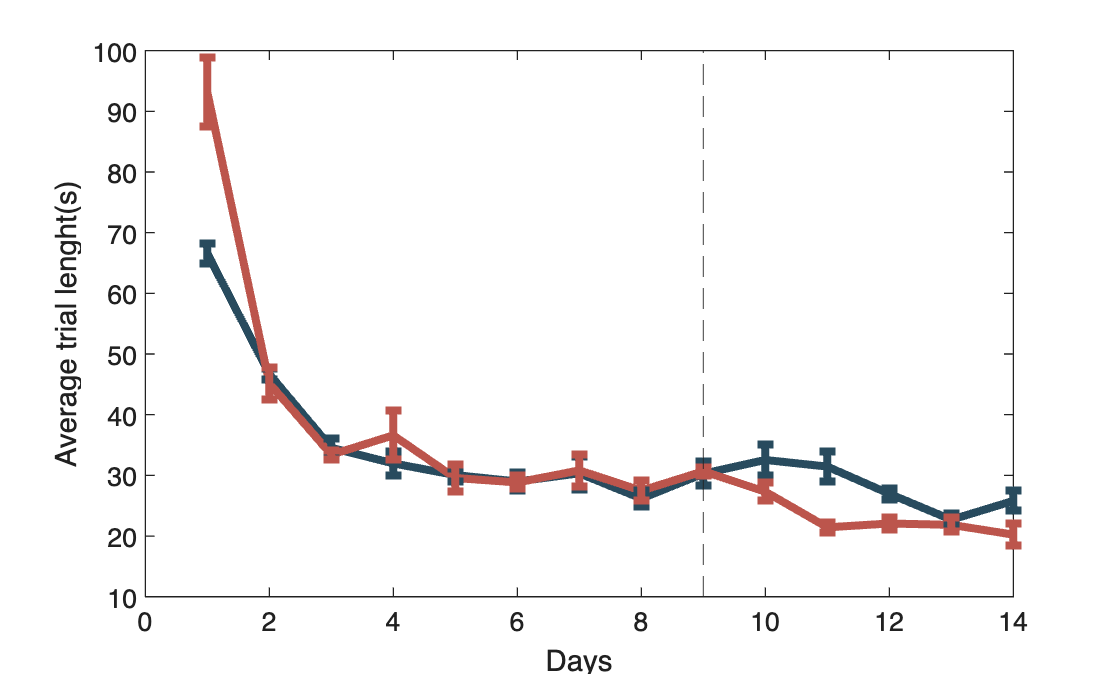


figure
c = plot(trial_genotype,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Days');
ylabel('Average trial lenght(s)');
er = errorbar(trial_genotype,trial_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
xline(9,'--');

[p,tbl,stats] = anova2(trial_genotype(1:8,:),2,"off");
vec = multcompare(stats,"Display","off");
tbl1 = array2table(vec,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit      A-B      Upper Limit    P-value
    _______    _______    ___________    _______    ___________    _______

       1          2         -18.806      -3.7119      11.382       0.58621

	Get insights using Copilot


[p,tbl,stats] = anova2(trial_genotype(9:end,:),2,"off");
vec = multcompare(stats,"Display","off");
tbl1 = array2table(vec,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 1×6 table
    Group A    Group B    Lower Limit     A-B      Upper Limit     P-value 
    _______    _______    ___________    ______    ___________    _________

       1          2         1.5013       4.3592       7.217       0.0097098

	Get insights using Copilot


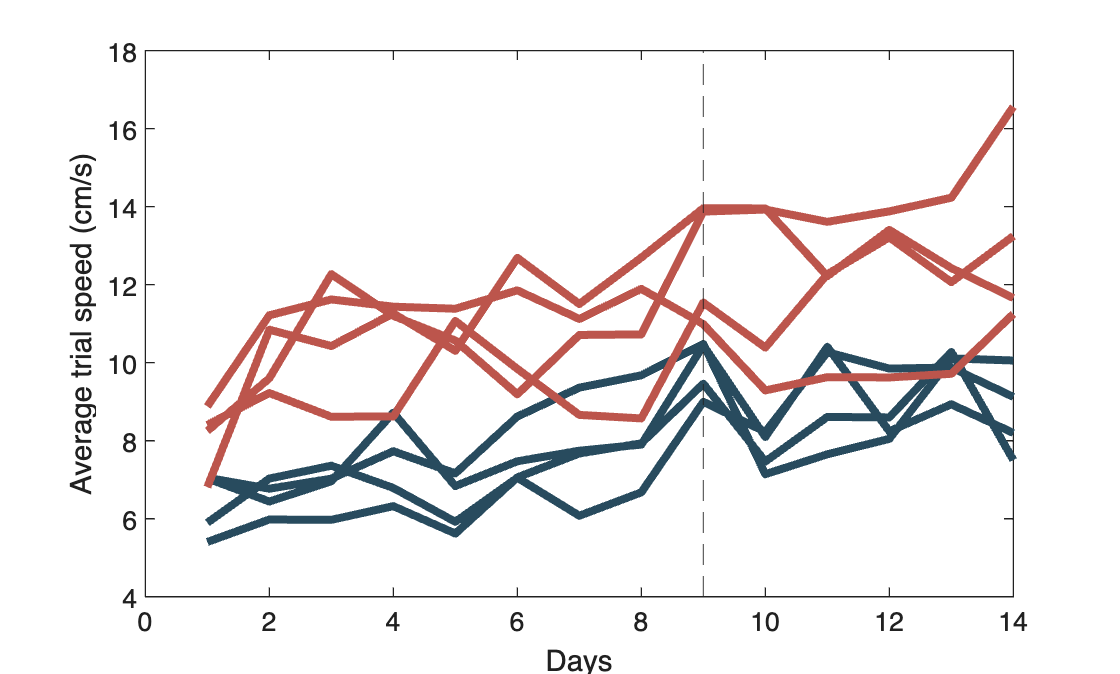

figure
plot(speed_day(:,negative),'Color',"#284B5E", 'LineWidth',3);
hold on
plot(speed_day(:,positive),'Color',"#BC554C", 'LineWidth',3);
xlabel('Days');
ylabel('Average trial speed (cm/s)');
xline(9,'--');

## Speed different during perfect trials?

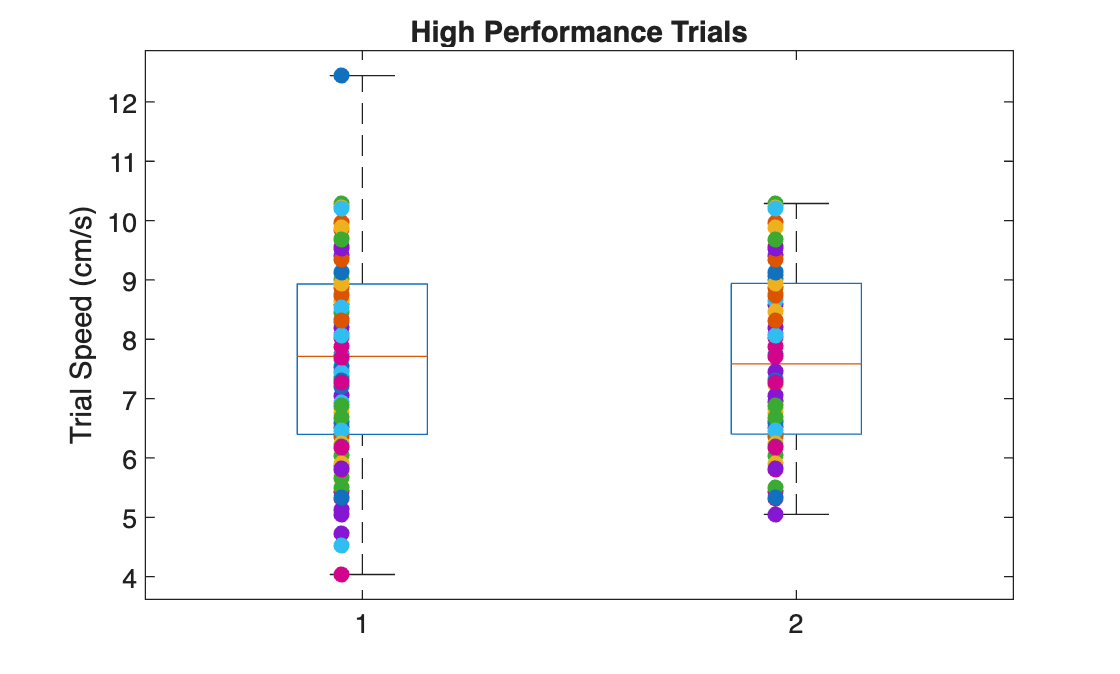

[r,s] = size(total_error);
speed_perfect = nan(r,s);
speed_errors = speed_avr;
for i = 1:animals

    idx = find(total_error(:,i) == 0);

    speed_perfect(idx,i) = speed_avr(idx);

    speed_errors(idx,1) = NaN;

end

[~,edges] = histcounts(speed_perfect(:,[negative,positive]));

histogr = histcounts(speed_perfect(:,negative),edges)./length(negative);
histogr2 = histcounts(speed_perfect(:,positive),edges)./length(positive);



vec = average_matrix(speed_perfect,animals,8);
[s_perfect, s_perfect_se] = genotype(vec,negative,positive);


speed_perf_box = [mean(speed_perfect(:,negative),2,'omitnan'),mean(speed_perfect(:,positive),2,'omitnan')];
[h,p] = ttest2(speed_perf_box(:,1),speed_perf_box(:,2));


figure
boxplot(speed_perf_box)
hold on
scatter(1,speed_perf_box(:,1),'filled','filled','jitter','on','jitterAmount',0.08)
scatter(2,speed_perf_box(:,2),'filled','filled','jitter','on','jitterAmount',0.08)
ylabel('Trial Speed (cm/s)')
title('High Performance Trials')

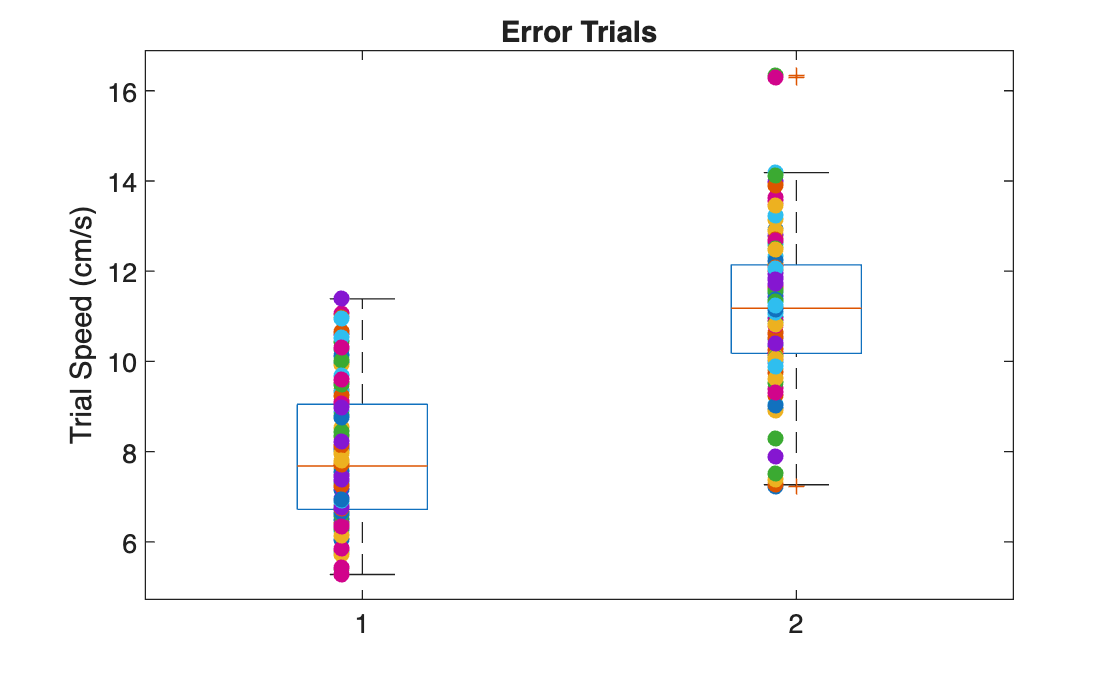


% speed_err_box = [reshape(speed_errors(6:end,negative),[numel(speed_errors(6:end,negative)),1]), reshape(speed_errors(6:end,positive),[numel(speed_errors(6:end,positive)),1])];
speed_err_box = [mean(speed_errors(6:end,negative),2,'omitnan'),mean(speed_errors(6:end,positive),2,'omitnan')];
[h,p] = ttest2(speed_err_box(:,1),speed_err_box(:,2));

figure
boxplot(speed_err_box)
hold on
scatter(1,speed_err_box(:,1),'filled','filled','jitter','on','jitterAmount',0.08)
scatter(2,speed_err_box(:,2),'filled','filled','jitter','on','jitterAmount',0.08)
ylabel('Trial Speed (cm/s)')
title('Error Trials')